
$$D=c+\frac{b}{X-a}$$


X es el valor normalizado de R, G, B

R: 0.0450380826239147 2.11956671492532 -3.28368654895324

G: 0.0171158657931860 3.02794588913442 -4.75872048307099

B: -0.133044775671637 14.9927317017188 -26.2991652925775

clear variables;
%clear all;
maxBitNumber=65535;

%Cargar Radiocrómicas
filmPath = 'RC1(sin)-buena.tif';
recorte=[29.5 169.5 1025 1230];
I1 = imread(filmPath);
I1R = imcrop(I1,recorte);
R1R = double(I1R(:,:,1)) / maxBitNumber;
G1R = double(I1R(:,:,2)) / maxBitNumber;
B1R = double(I1R(:,:,3)) / maxBitNumber;

filmPath2 = 'RC1(sin)-buena (2).tif';
I2 = imread(filmPath2);
I2R = imcrop(I2,recorte);
R2R = double(I2R(:,:,1)) / maxBitNumber;
G2R = double(I2R(:,:,2)) / maxBitNumber;
B2R = double(I2R(:,:,3)) / maxBitNumber;

filmPath3 = 'RC1(sin)-buena (3).tif';
I3 = imread(filmPath3);
I3R = imcrop(I3,recorte);
R3R = double(I3R(:,:,1)) / maxBitNumber;
G3R = double(I3R(:,:,2)) / maxBitNumber;
B3R = double(I3R(:,:,3)) / maxBitNumber;

filmPath4 = 'RC1(sin)-buena (4).tif';
I4 = imread(filmPath4);
I4R = imcrop(I4,recorte);
R4R = double(I4R(:,:,1)) / maxBitNumber;
G4R = double(I4R(:,:,2)) / maxBitNumber;
B4R = double(I4R(:,:,3)) / maxBitNumber;


### Sacar promedios con errores

% Media
juntasR = zeros(recorte(4)+1,recorte(3)+1,3,4);

% Rojo
juntasR(:,:,1,1) = R1R;
juntasR(:,:,1,2) = R2R;
juntasR(:,:,1,3) = R3R;
juntasR(:,:,1,4) = R4R;

% Verde
juntasR(:,:,2,1) = G1R;
juntasR(:,:,2,2) = G2R;
juntasR(:,:,2,3) = G3R;
juntasR(:,:,2,4) = G4R;

% Azul 
juntasR(:,:,3,1) = B1R;
juntasR(:,:,3,2) = B2R;
juntasR(:,:,3,3) = B3R;
juntasR(:,:,3,4) = B4R;

%Desviación estándar de las matrices pixel a pixel de la 4 dimensión
desvRR = std(juntasR(:,:,1,:),0,4)

desvRR =     0.0007    0.0010    0.0017    0.0015    0.0010    0.0014    0.0008    0.0038    0.0010    0.0011    0.0010    0.0013    0.0017    0.0007    0.0007    0.0011    0.0023    0.0014    0.0012    0.0022    0.0026    0.0008    0.0020    0.0010    0.0014    0.0019    0.0018    0.0017    0.0028    0.0016    0.0014    0.0024    0.0013    0.0015    0.0007    0.0008    0.0004    0.0010    0.0017    0.0028    0.0018    0.0015    0.0013    0.0013    0.0010    0.0022    0.0009    0.0018    0.0019    0.0002
    0.0012    0.0017    0.0015    0.0010    0.0010    0.0006    0.0020    0.0017    0.0015    0.0013    0.0014    0.0007    0.0014    0.0005    0.0013    0.0012    0.0012    0.0008    0.0014    0.0012    0.0007    0.0016    0.0022    0.0009    0.0002    0.0007    0.0012    0.0010    0.0010    0.0015    0.0005    0.0013    0.0013    0.0013    0.0009    0.0009    0.0015    0.0010    0.0023    0.0026    0.0018    0.0013    0.0013    0.0025    0.0007    0.0012    0.0002    0.0013    0.0009

desvGR = std(juntasR(:,:,2,:),0,4)

desvGR =     0.0012    0.0014    0.0003    0.0004    0.0020    0.0006    0.0013    0.0036    0.0010    0.0013    0.0013    0.0011    0.0004    0.0010    0.0006    0.0005    0.0016    0.0007    0.0009    0.0014    0.0012    0.0005    0.0014    0.0013    0.0004    0.0015    0.0013    0.0018    0.0021    0.0015    0.0020    0.0012    0.0011    0.0016    0.0021    0.0014    0.0006    0.0011    0.0013    0.0013    0.0019    0.0010    0.0002    0.0005    0.0010    0.0011    0.0006    0.0011    0.0010    0.0008
    0.0018    0.0023    0.0015    0.0006    0.0007    0.0003    0.0027    0.0017    0.0015    0.0011    0.0010    0.0008    0.0014    0.0012    0.0011    0.0020    0.0022    0.0009    0.0010    0.0018    0.0004    0.0010    0.0014    0.0011    0.0008    0.0018    0.0007    0.0007    0.0008    0.0018    0.0011    0.0015    0.0014    0.0011    0.0011    0.0014    0.0011    0.0008    0.0018    0.0018    0.0021    0.0016    0.0019    0.0033    0.0016    0.0011    0.0014    0.0016    0.0007

desvBR = std(juntasR(:,:,3,:),0,4)

desvBR =     0.0027    0.0028    0.0039    0.0026    0.0026    0.0039    0.0031    0.0038    0.0030    0.0036    0.0036    0.0030    0.0029    0.0030    0.0029    0.0031    0.0037    0.0037    0.0036    0.0042    0.0028    0.0032    0.0026    0.0027    0.0030    0.0036    0.0030    0.0028    0.0028    0.0027    0.0031    0.0029    0.0030    0.0030    0.0036    0.0027    0.0029    0.0031    0.0024    0.0035    0.0036    0.0028    0.0028    0.0035    0.0032    0.0029    0.0034    0.0032    0.0024    0.0028
    0.0027    0.0030    0.0032    0.0026    0.0021    0.0032    0.0035    0.0027    0.0027    0.0031    0.0029    0.0032    0.0030    0.0037    0.0035    0.0029    0.0038    0.0032    0.0031    0.0039    0.0029    0.0033    0.0029    0.0026    0.0025    0.0034    0.0033    0.0024    0.0028    0.0029    0.0023    0.0025    0.0028    0.0027    0.0036    0.0025    0.0028    0.0024    0.0037    0.0036    0.0031    0.0026    0.0033    0.0029    0.0030    0.0031    0.0034    0.0029    0.0026


%Matriz promedio
mediaRR = mean(juntasR(:,:,1,:),4);
mediaGR = mean(juntasR(:,:,2,:),4);
mediaBR = mean(juntasR(:,:,3,:),4);


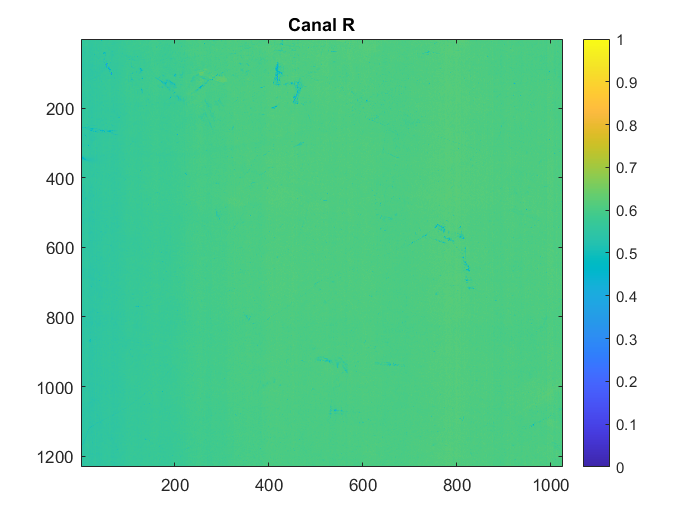


% Definimos la función para cada uno de los canales
aR=0.0450380826239147; bR=2.11956671492532; cR=-3.28368654895324;
aG=0.0171158657931860; bG=3.02794588913442; cG=-4.75872048307099;
aB=-0.133044775671637; bB=14.9927317017188; cB=-26.2991652925775;


DR = @(mediaRR) cR + bR ./ (mediaRR - aR);
PVG = @(mediaGR) aG + bG ./ (mediaGR - cG);
PVB = @(mediaBR) aB + bB ./ (mediaBR - cB);


% Pintamos la dosis por separados
DR = DR(mediaRR);
imagesc(DR)
%imagesc(mediaRR)
caxis([0 1])
colorbar
title('Canal R')

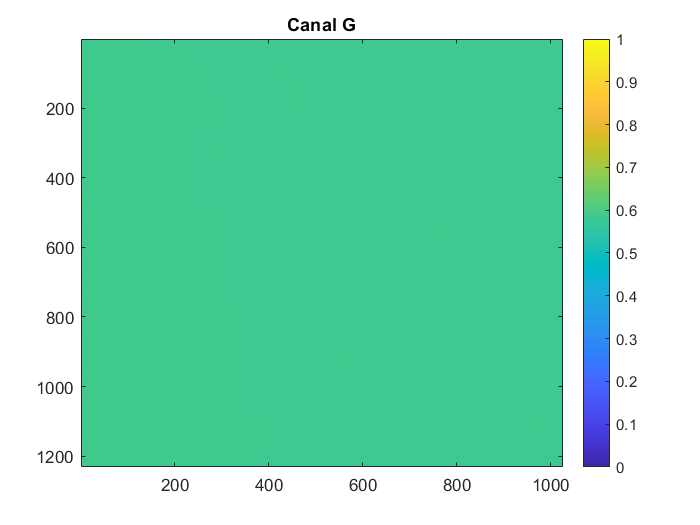


PVG = PVG(mediaGR);
imagesc(PVG)
caxis([0 1])
colorbar
title('Canal G')

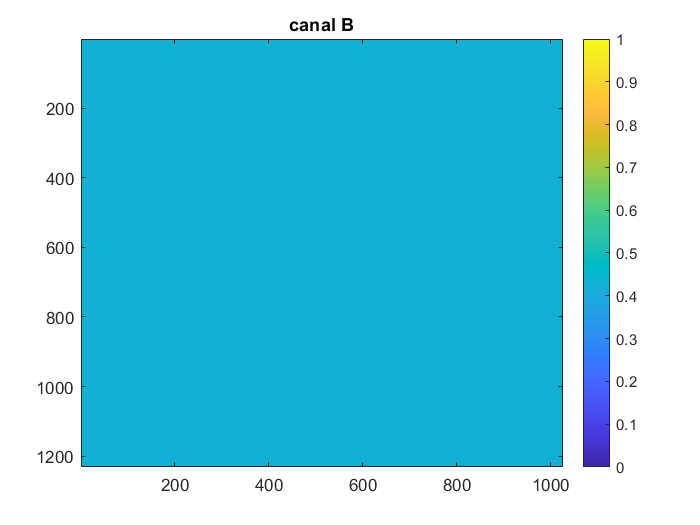

 
PVB = PVB(mediaBR);
imagesc(PVB)
caxis([0 1])
colorbar
title('canal B')


% Obtenemos la dosis mediante una media ponderada y representamos
% DeltaR=@(PVR) bR.*(desvRR)./(PVR-aR).^2
% DeltaG=@(PVG) bG.*(desvGR)./(PVG-aG).^2
% DeltaB=@(PVB) bB.*(desvBR)./(PVB-aB).^2
DeltaR= bR.*(desvRR)./(DR-aR).^2;
DeltaG= bG.*(desvGR)./(PVG-aG).^2;
DeltaB= bB.*(desvBR)./(PVB-aB).^2;
DT=(DR.*(DeltaR)+PVG.*(DeltaG)+PVB.*(DeltaB))./((DeltaR)+(DeltaG)+(DeltaB))

DT =     0.4303    0.4307    0.4303    0.4300    0.4306    0.4299    0.4302    0.4327    0.4300    0.4299    0.4298    0.4303    0.4299    0.4307    0.4303    0.4300    0.4313    0.4299    0.4300    0.4307    0.4312    0.4300    0.4306    0.4301    0.4300    0.4307    0.4304    0.4306    0.4314    0.4303    0.4305    0.4307    0.4301    0.4303    0.4305    0.4300    0.4299    0.4305    0.4308    0.4317    0.4307    0.4302    0.4301    0.4298    0.4300    0.4305    0.4305    0.4301    0.4304    0.4295
    0.4309    0.4310    0.4303    0.4298    0.4300    0.4296    0.4312    0.4307    0.4303    0.4301    0.4300    0.4298    0.4301    0.4299    0.4300    0.4304    0.4306    0.4300    0.4301    0.4303    0.4304    0.4305    0.4306    0.4307    0.4302    0.4303    0.4299    0.4301    0.4299    0.4304    0.4296    0.4304    0.4302    0.4300    0.4306    0.4304    0.4304    0.4302    0.4312    0.4313    0.4309    0.4302    0.4305    0.4320    0.4300    0.4302    0.4303    0.4304    0.4298    

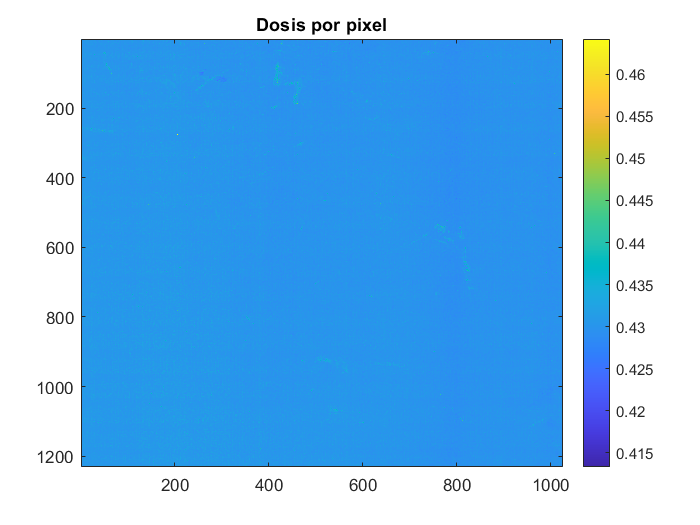

imagesc(DT)
colorbar
title('Dosis por pixel')